# Script to Analyze LearnSmart Data

Created on: 18 Jan 2019

Samuel Bechara, PHD

Assistant Professor of Practice

Biomedical and Mechanical Engineering

Colorado State University

% MATLAB Setup
clear
clc
close all

load data.mat

x = mcGrawHillALL18LearnSmart.TimeSpentMin;
y = mcGrawHillALL18LearnSmart.FinalCourseScore;

## Linear Regression

The first idea was to see if there was a linear relationship between time spent reading and the final grade in the course.

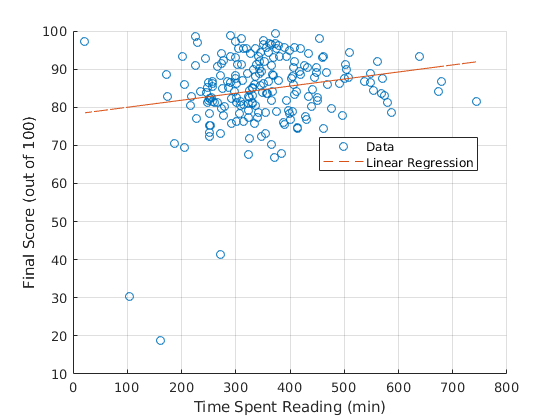


% b1 is the slope or regression coefficient
b1 = x\y;

% Calculate the score per LearnSmartMin using the relation. 
scatter(x,y);

hold on

% Improve the fit by including a y-intercept
X = [ones(length(x),1) x];
b = X\y;
yCalc2 = X*b;
plot(x,yCalc2,'--')
legend('Data','Linear Regression','Location','best');
xlabel('Time Spent Reading (min)')
ylabel('Final Score (out of 100)')
%title('Linear Regression Relation Between LearnSmart Time & Final Grade')


% line([timeThreshold timeThreshold],[10 100],'Color','black','LineStyle','--')
grid on
hold off


% Calculate R-Squared
Rsq2 = 1 - sum((y - yCalc2).^2)/sum((y - mean(y)).^2)

Rsq2 = 0.0372

The results from this section indiated that there was not a linear relationship between time spent reading and overall grade.

## Test Sample Means - 2 Sample Unpaired T-Test

timeThreshold = mean(mcGrawHillALL18LearnSmart.TimeSpentMin);

j = 1;
for i = 1:length(mcGrawHillALL18LearnSmart.FinalCourseScore)
    if mcGrawHillALL18LearnSmart.TimeSpentMin(i) < timeThreshold
        LTC_Score(j)=mcGrawHillALL18LearnSmart.FinalCourseScore(i);
        LTC_Time(j)=mcGrawHillALL18LearnSmart.TimeSpentMin(i);
        j = j + 1;
    end
end

j = 1;
for i = 1:length(mcGrawHillALL18LearnSmart.FinalCourseScore)
    if mcGrawHillALL18LearnSmart.TimeSpentMin(i) > timeThreshold
        HTC_Score(j)=mcGrawHillALL18LearnSmart.FinalCourseScore(i);
        HTC_Time(j)=mcGrawHillALL18LearnSmart.TimeSpentMin(i);
        j = j + 1;
    end
end

% Calc and display basic stats
avgLTC_Score = mean(LTC_Score)

avgLTC_Score = 83.4526

avgHTC_Score = mean(HTC_Score)

avgHTC_Score = 86.3449


medLTC_Time = mean(LTC_Time)

medLTC_Time = 286.8158

medHTC_Time = mean(HTC_Time)

medHTC_Time = 443.8391


[h,p,ci,stats] = ttest2(LTC_Score,HTC_Score)

h = 1

p = 0.0404

ci =    -5.6568   -0.1278


stats = struct with fields:
    tstat: -2.0631
       df: 199
       sd: 9.8478


[h_time,p_time_ci_time,stats_time] = ttest2(LTC_Time,HTC_Time)

h_time = 1

p_time_ci_time = 2.2781e-38

stats_time =  -176.0707 -137.9758


## Boxplot of Time Spent Reading

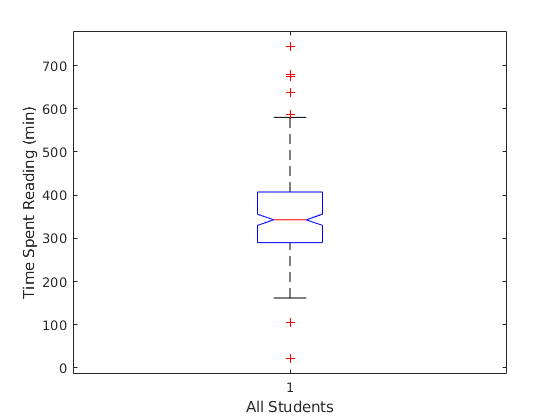

figure

% Boxplot total time reading
boxplot(x,'Notch','on')
xlabel('All Students')
ylabel('Time Spent Reading (min)')


% Since each student was assigned 15 chapeters, calc min/chapter
min_per_chapter = timeThreshold/15;

## Bar Chart for Mean Time

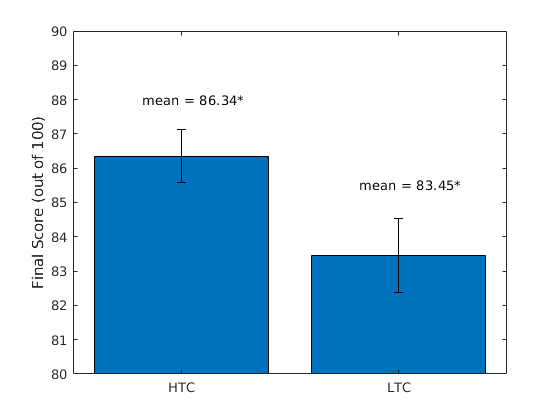

figure
c = categorical({'LTC','HTC'});
bar(c,[mean(LTC_Score),mean(HTC_Score)]);
ylim([80 90])
ylabel('Final Score (out of 100)')
text(1-0.18,88,'mean = 86.34*')
text(2-0.18,85.5,'mean = 83.45*')
stdEr_LTC = std(LTC_Score)/sqrt(length(LTC_Score));
stdEr_HTC = std(HTC_Score)/sqrt(length(HTC_Score));

errlow=[stdEr_LTC stdEr_HTC];
errhigh = errlow;

hold on

er = errorbar(c,[mean(LTC_Score),mean(HTC_Score)],errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

### Create Publishable Scatter Plot

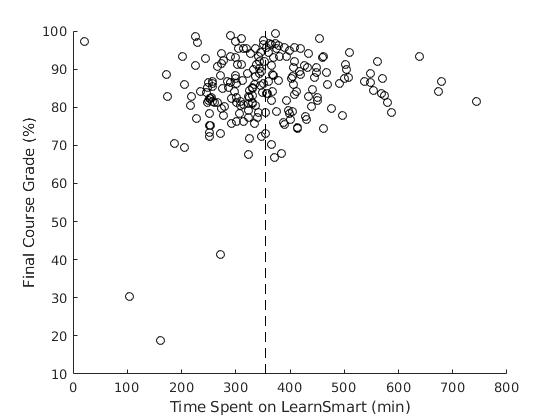

figure
scatter(x,y,'black')
xlabel('Time Spent on LearnSmart (min)')
ylabel('Final Course Grade (%)')
line([timeThreshold timeThreshold],[10 100],'Color','black','LineStyle','--')